Laborator 8 - Interpolare spline

P1. Pentru fiecare tip de spline, scrieți o funcție care calculează coeficienții spline-ului, dacă se dau nodurile și valorile funcției.

P2. Evaluați spline-ul pe o mulțime de puncte, dacă se dau nodurile, punctele și coeficienții.

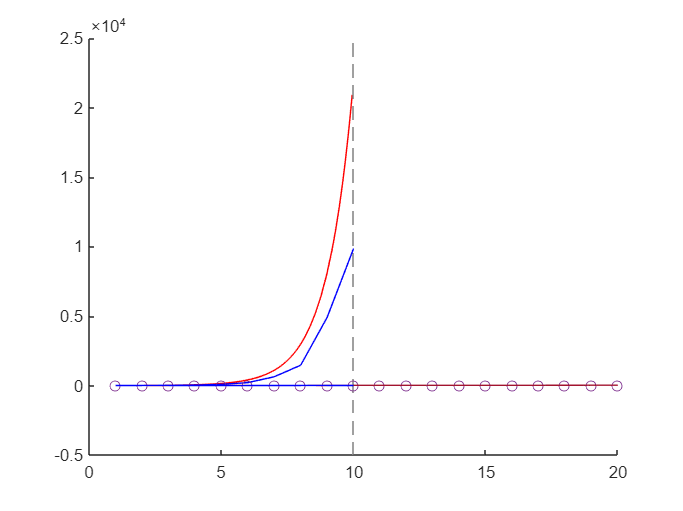

x = [1 : 20];
t = [0.5 : 1 : 9.5];

f = sin(x);
fderiv = cos(x);

hold on;
fplot(@sin, [1, 10], 'r');

[a, b, c, d] = CubicSpline(x, f, 0, fderiv);
result = evaluate_spline(x, a, b, c, d, t);
%fprintf("%f", result);
plot(result, 'b');

P3. Desenați o curbă spline cubică parametrică ce trece printr-o mulțime de puncte date.

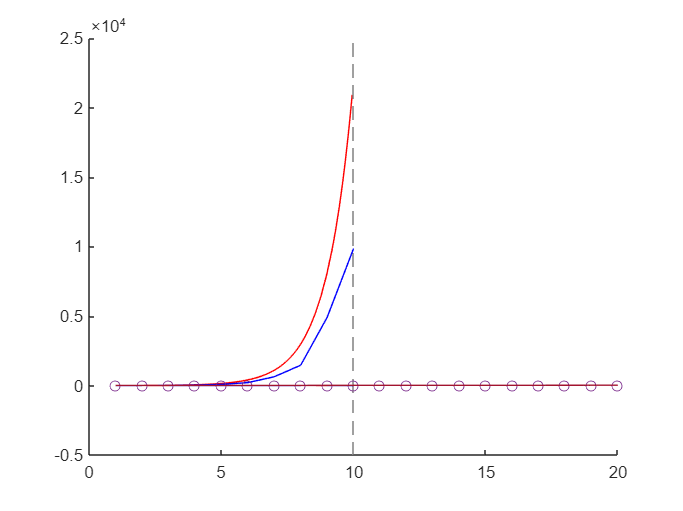

x = [1 : 20];
y = [1 : 20];

n = length(x);
tn = 0 : n - 1;
tg = linspace(0, n - 1, 1000);
xg = spline(tn, x, tg);
yg = spline(tn, y, tg);
plot(x, y, xg, yg);